s = rng(2018);
theta = 2*pi*rand(1,2)

theta =     5.5440    0.6555


theta_a = theta(1,1)

theta_a = 5.5440

theta_b = theta(1,2)

theta_b = 0.6555



theta_A = (theta_a*180/pi)

theta_A = 317.6458

theta_B = (theta_b*180/pi)

theta_B = 37.5580

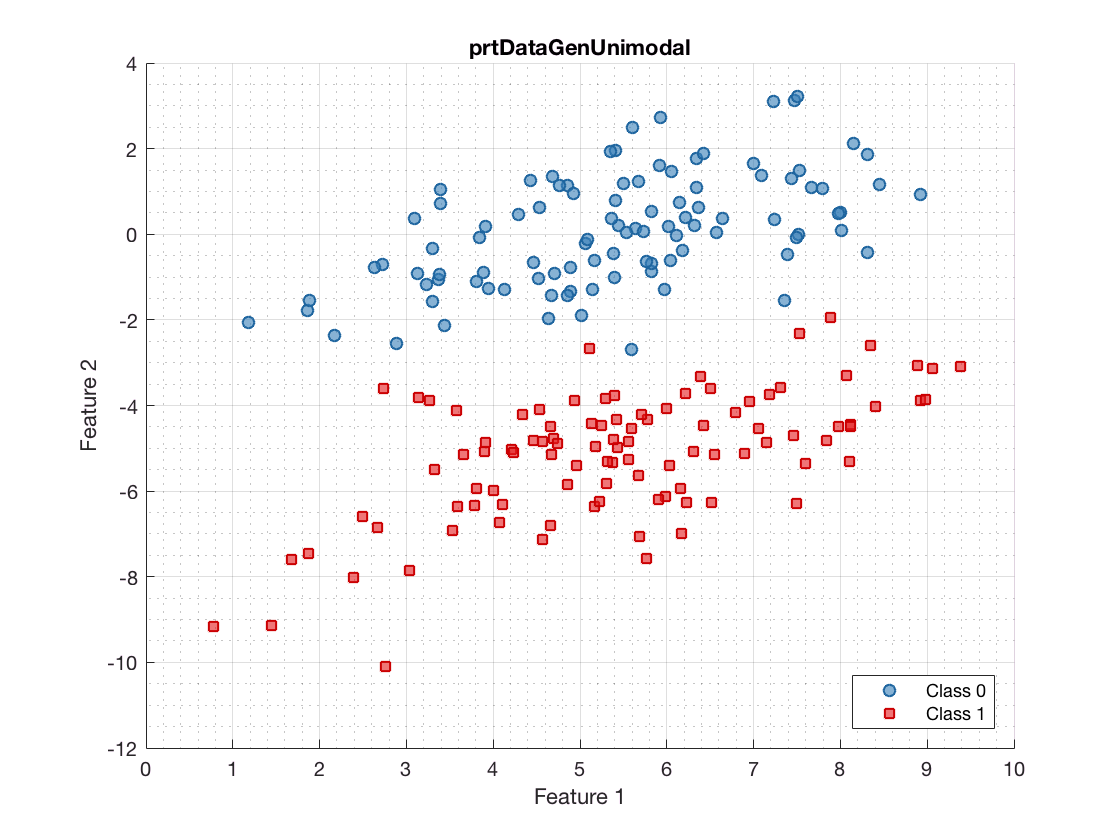


M0 = [5.4845,0];
M1 = [5.4845,-5];

sigma1 = [cosd(theta_B), -sind(theta_B) ; sind(theta_B), cosd(theta_B)]*...
    [4,0;0,1]*[cosd(theta_B), -sind(theta_B); sind(theta_B), cosd(theta_B)]';
sigma0 = sigma1;

dstrain = prtDataGenUnimodal(100,M0,M1,sigma0,sigma1);
plot(dstrain)

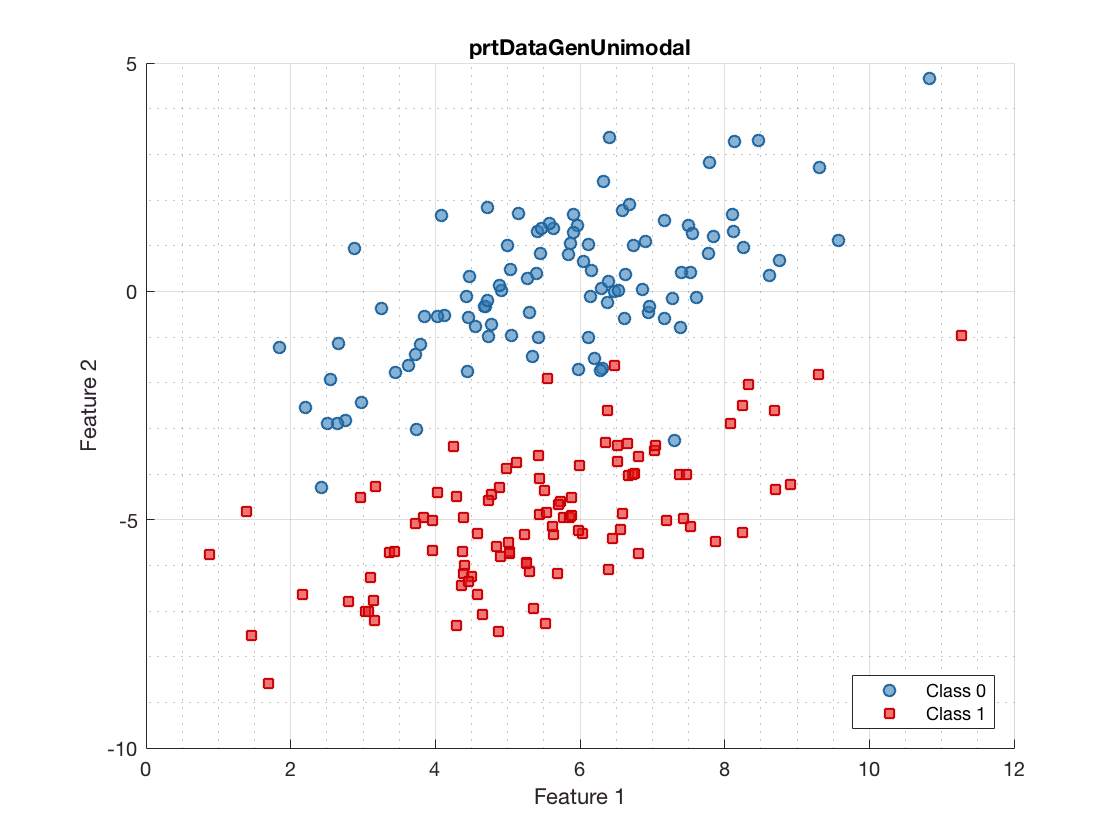

dstest = prtDataGenUnimodal(100,M0,M1,sigma0,sigma1);
plot(dstest)

prtClassFld.f